## Variables

siz = 50:1500;
r = siz./2;
nm = 1.337;
ns = 1.463;
lambda= 488;
k = (2*pi*nm)/lambda;
NA = 1.018;
nang = 200;
pang=linspace(0.706,2.430,nang);
conv = 1;
filename='df_Jan_apogee.xls';
alpha = asind(NA./nm).*pi./180;
% thetamin =  pi./2 - alpha  ; %angulos en radianes
% thetamax =  pi./2 + alpha  ;  
% phimin = @(theta) asin(sin(pi./2-alpha)./sin(theta)); 
% phimax = @(phimin) pi-phimin ;

## Coated EV model

size = 50:1500;
re = size./2 ; 
mbthick= 5 ;
ri = re-mbthick ;
coatsph = [];
RIi = 1.36 ;
RIe = 1.48 ;
nscoat = [RIi,RIe];

## Matrices

ES = zeros(1,2,nang,length(r));

## Bucle

for rad = 1:length(r)
    [S, C, ang] = calcmie( r(rad), ns, nm, lambda, nang, 'ConvergenceFactor', 1);
    for p = 1:nang
        ES(:,1,p,rad) = abs(S(2,2,p)).^2;
        ES(:,2,p,rad) = abs(S(1,1,p)).^2;
    end

end

## Bucle coat

for rad = 1:length(size)
    coatsph = [ri(rad),re(rad)];
    [S, C, ang] = calcmie( coatsph, nscoat, nm, lambda, nang, 'ConvergenceFactor', 1);
    for p = 1:nang
        ES(:,1,p,rad) = abs(S(2,2,p)).^2;
        ES(:,2,p,rad) = abs(S(1,1,p)).^2;
    end
end

## Integration

dif = (pang(end)-pang(1))./length(pang);
scat = zeros(1,length(r));
% sumry= zeros(length(pang),6);
for j = 1:length(r)
    sumscat = 0;
    for i = 1:length(pang)
        thetamin = (pang(i)-dif);
        thetamax = (pang(i)+dif);
        %thetas = mean([thetamax,thetamin]);
        phimin = asin(sin(pi./2-alpha)./sin(pang(i))) ;
        phimax = pi-phimin;
        f = @(theta,phi) (ES(1,1,i,j).*sin(phi).^2 + ES(1,2,i,j).*cos(phi).^2)./(k.^2).*sin(theta);
        res = integral2(f,thetamin,thetamax,phimin,phimax);
        sumscat = sumscat + res;
%         sumry(i,1) = pang(i);
%         sumry(i,2) = res;
%         sumry(i,3) = thetamin;
%         sumry(i,4) = thetamax;
%         sumry(i,5) = phimin;
%         sumry(i,6) = phimax;
    end
    scat(j) = sumscat;
    disp(j)
end


## Plot

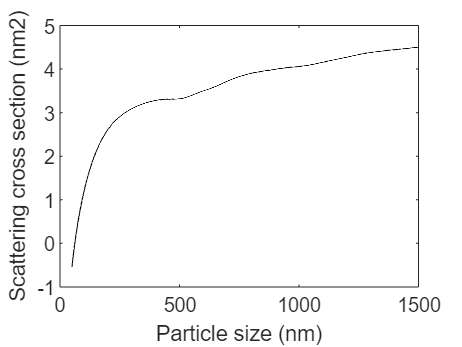

scatlog = log10(scat);
ds = [siz; scatlog]';
plot(siz,scatlog, Color='black')
%hold on
%plot(siz,sctcoatlog, Color='black')
%hold off
xlabel('Particle size (nm)')
ylabel('Scattering cross section (nm2)')

## Export data

df = [siz; scat]';
writematrix(df,filename)